# Nonlinear standing wave on a semi-infinite lasso graph

First, set up the folder to house the solutions and the quantum graph.

tag='lasso';
Phi=quantumGraphFromTemplate(tag,'LVec',[2*pi inf]);%,'Discretization','Chebyshev','nX',64);
dataDir = makeContinuationDirectory(Phi,tag);

Created directory data/lasso/044.


Set up the functions needed for the nonlinear solver and continuation program using the default value $f(z)=2z^3$

saveNLSFunctionsGraph(dataDir,Phi);

Solve the nonlinear standing wave equation from an initial guess with a bump on edge $\mathtt{e}_2$.

PhiGuess=Phi.applyFunctionsToAllEdges({@(x)sin(x-2*pi/3),@(x)sin(pi/3)*exp(-x)});

options=continuerSet([],'LambdaThresh',-3,'NThresh',9,'plotFlag',false,'minNormDelta',1e-3);

nSolutions = 2;

[fileNumber,uComputed] = ...
    saveDeflatedStandingWaves(dataDir,Lambda0,PhiGuess,nSolutions);

File saved to data/lasso/044/savedFunction.001.
File number is 1. 
File saved to data/lasso/044/savedFunction.002.
File number is 2. 


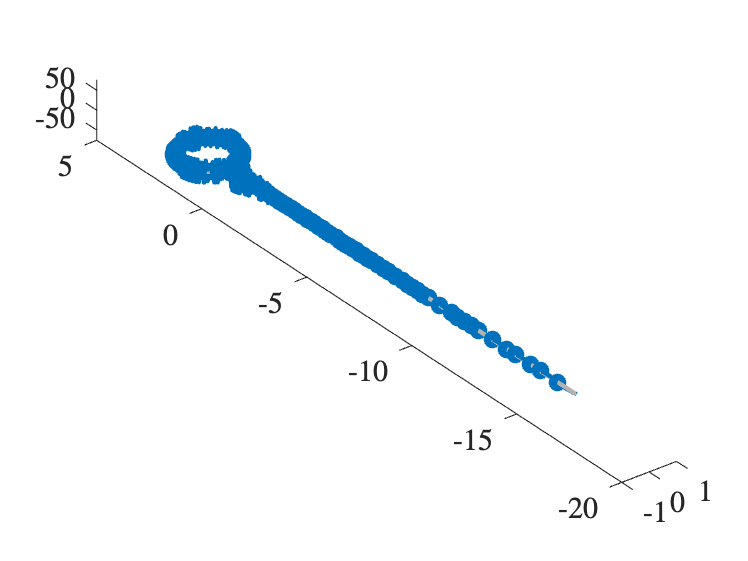

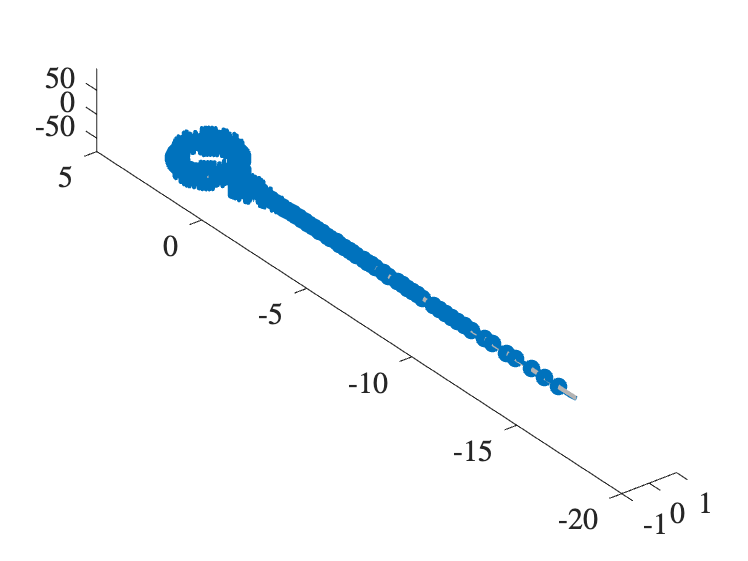


for k = 1:nSolutions
    figure;
    Phi.plot(uComputed(:,k))
end